# Model fits to tongue and lip (Figures 5-9)

**Repository dependencies:  **ISETCam, isetfluorescence

This script creates the individual fits of the model in Figures 5-9.  It also creates the data for Tables 1 and 2.

## Stage 1 (oeSolveJoint).

We fix a matrix with collagen1-smooth, FAD_webfluor, porphyrin and chlorophyll excitations. We choose these four because the first two fit the lip data well.  This guarantees that we will be able to find a fit to the lip data at the end.

We use oeSolveJoint to do two things.  

- Vary the blood oxygen of collagen, and 

- Search for one more, additional fluorophore, specified only as a skewed Gaussian with three parameters (mean, width, skew), to improve the fit. 

The additional (fifth) fluorophore is a stand-in for keratin, which is present on the tongue, but not on the lip.  We call this estimated fluorophore pseudo-keratin.

In the initial stage of the fit, we use the same blood density for all subjects.  The purpose of this stage is to learn about the parameters of the skewed Gaussian, which we store and use later.

## Stage 2 (oeSolveBlood)

We confirm that we can fit the lip data with just the collagen and FAD, searching for blood.  This is for the group lipData.

## Stage 3 (oeSolveBlood)

We loop through the subjects.  

For the tongue, we use the five fluorophores (collagen, FAD, porphyrin, chlorophyll, pseudo-keratin) and solve for the blood in each subject.

For the lip, we use only two fluorophores (collagen, FAD) and solve for the blood in each subject.

## Initialize script-wide parameters

ieInit;
wave = 500:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
fise_plotDefaults;
subjects = oeSubjects;
[T,dataDir] = oeDatabaseCreate;

## Load the  tongue data in the two excitation wavelength grups

Here, we load all of the subjects into a single large data set for tongue. In this case we group the 405 and 415 nm excitation lights.  We put the tongue and lip data, normalized at nWave, on the same graph.  We fit these to find the pseudo-keratin.

tongueData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    tongueData = cat(2,tongueData,tmp);
end

tongueData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave); 
    tongueData450 = cat(2,tongueData450,tmp);
end


## Load the fixed fluorophores

These are stored in the isetfluorescence repository.  That is needed for this paper.

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor','PorphyrinBjurshammar','chlorophyllA-7'};
[fixedFluorophores,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## Call the joint search

We have fluorophores for the lip that fit well if we adjust the blood density (per subject).  Those are collagen1-smooth and FAD_webfluor.  We fix those two fluorophores.  We also know the emission spectra of porphyrins and chlorophyll-a.  These four are contained in the fixedFluorophores variable.

Here, we estimate the emission spectrum of keratain, which we call pseudo-keratin. We do the fit by pooling the tongue data from all the subjects and searching for a mean blood optical density and an additional fluorophore (basis) that is modeled as a skewed Gaussian. oeSolveJoint returns four weights.  The first is the optical blood density.  The next three are the three parameters of the fitted skewedGaussian.  It also returns the skewedGaussian as a column in the finalFluorophores matrix.

The five columns of finalFluorophores are:  collagen1-smooth, FAD_webfluor, porphyrin, chlorophyll, pseudo-keratin/  

[global_params, weights, finalFluorophores] = oeSolveJoint(wave, tongueData, fixedFluorophores);
disp(global_params);

   11.2290  425.0961  386.6748    5.0000



od = global_params(1);

We will want these columns.  We keep them in savedFluorophores are the original fluorophores **without** blood and the newly estimated pseudo-keratin fluorophore. These are the fluorophores we use these later when we search for the blood density in individual subjects. When we solve for the finalFluorophores in each fit, it adjusts the savedFluorophores by putting the blood into the collagen-smooth column.  That's why we need to start the fits with the savedFluorophores.  The finalFluorophores have the blood attenuated collagen, which is fit to each subject.

Note:  When we fit the lip data, we do not use the last three fluorophores (porphyrins, chlorophyll-a, pseudo-keratin).  So the lipFluorophores are only blood attenuated collagen and FAD.

savedFluorophores = [fixedFluorophores,finalFluorophores(:,end)];

## Show the fluorophores and blood incorporated (Figure 5)

The finalFluorophores have blood-attenuated collagen and pseudo-keratin.  We plot them scaled by the typical weight we find in the solution

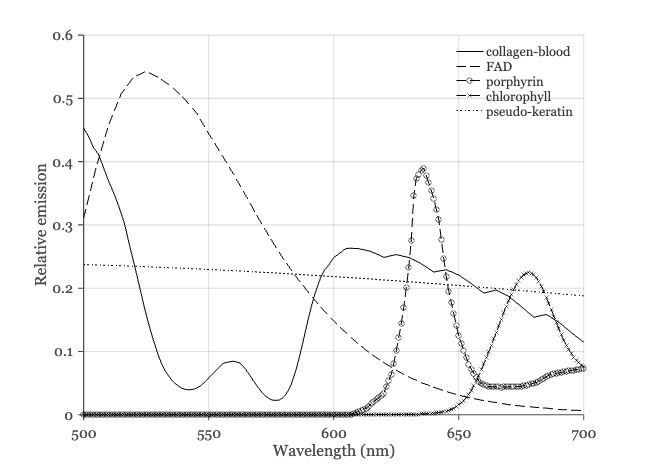

weightedFluorophores = finalFluorophores*diag(mean(weights,2));

ieFigure; hold on;
symbols ={'k-','k--','k--o','k--x','k:'};
for ii=1:size(weightedFluorophores,2)
    plot(wave,weightedFluorophores(:,ii),symbols{ii}); 
end

grid on; xlabel('Wavelength (nm)'); ylabel('Relative emission');
legend('collagen-blood','FAD','porphyrin','chlorophyll','pseudo-keratin');
exportgraphics(gcf,'figure5B.png','Resolution',150)

## Load the lip data

lipData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    lipData = cat(2,lipData,tmp);
end 

lipData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);       
    lipData450 = cat(2,lipData450,tmp);
end 

## Fit the subjects individually (Figure 6)

For each subject, the tongue data with 405 and 415.  Use the five fluorophores to fit, adjusting only for the blood.

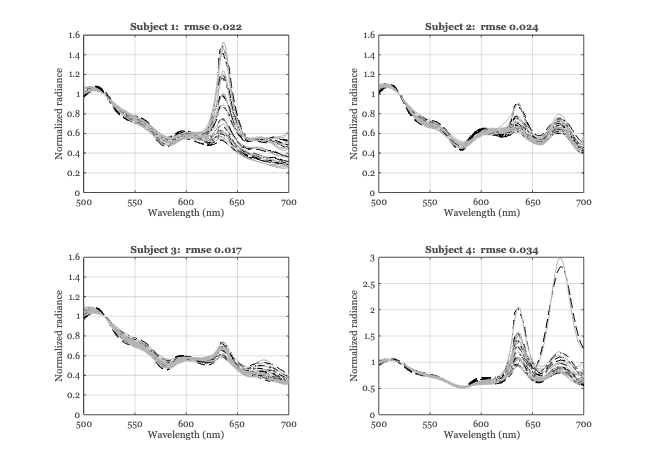

odTongue = zeros(1,numel(subjects));
weights = cell(4,1);
nTongue = zeros(1,numel(subjects));
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the tongue data
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    nTongue(ii) = size(tongueData,2);    

    % Find the blood optical density
    [odTongue(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,tongueData,savedFluorophores);
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,tongueData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance');
    set(gca,'ylim',[0 1.6]);
    if ii==4, set(gca,'ylim',[0 3]); end
    title(sprintf('Subject %d:  rmse %.3f',ii,rmse(tongueData(:),predicted(:))));
end
exportgraphics(gcf,'figure6.png','Resolution',150);

## Table of the tongue weights and blood od

Print the mean of the weights and the standard deviation

fluorophoreNames = ["Collagen", "FAD",  "Porphyrin", "Chlorophyll-a" "Keratin"];
oePrintModel(fluorophoreNames,odTongue,weights,nTongue);

Subject 1 (N=15):
Blood log10(od) 1.00  Collagen: 8.69 ± 1.07 FAD: 0.55 ± 0.05 Porphyrin: 0.42 ± 0.29 Chlorophyll-a: 0.04 ± 0.04 Keratin: 0.32 ± 0.08 

Subject 2 (N=14):
Blood log10(od) 1.07  Collagen: 13.18 ± 1.05 FAD: 0.55 ± 0.02 Porphyrin: 0.20 ± 0.09 Chlorophyll-a: 0.27 ± 0.04 Keratin: 0.23 ± 0.03 

Subject 3 (N=14):
Blood log10(od) 0.98  Collagen: 9.23 ± 1.16 FAD: 0.54 ± 0.02 Porphyrin: 0.19 ± 0.04 Chlorophyll-a: 0.04 ± 0.04 Keratin: 0.30 ± 0.05 

Subject 4 (N=15):
Blood log10(od) 1.12  Collagen: 10.72 ± 0.77 FAD: 0.52 ± 0.05 Porphyrin: 0.73 ± 0.30 Chlorophyll-a: 0.54 ± 0.51 Keratin: 0.36 ± 0.04 



## Fit the lip data to each individual (Figure 7)

For the lip, we only fit using the collagen and FAD data, adjusting for the blood.  We omit the porphyrins, chlorophyll and pseudo-keratin.

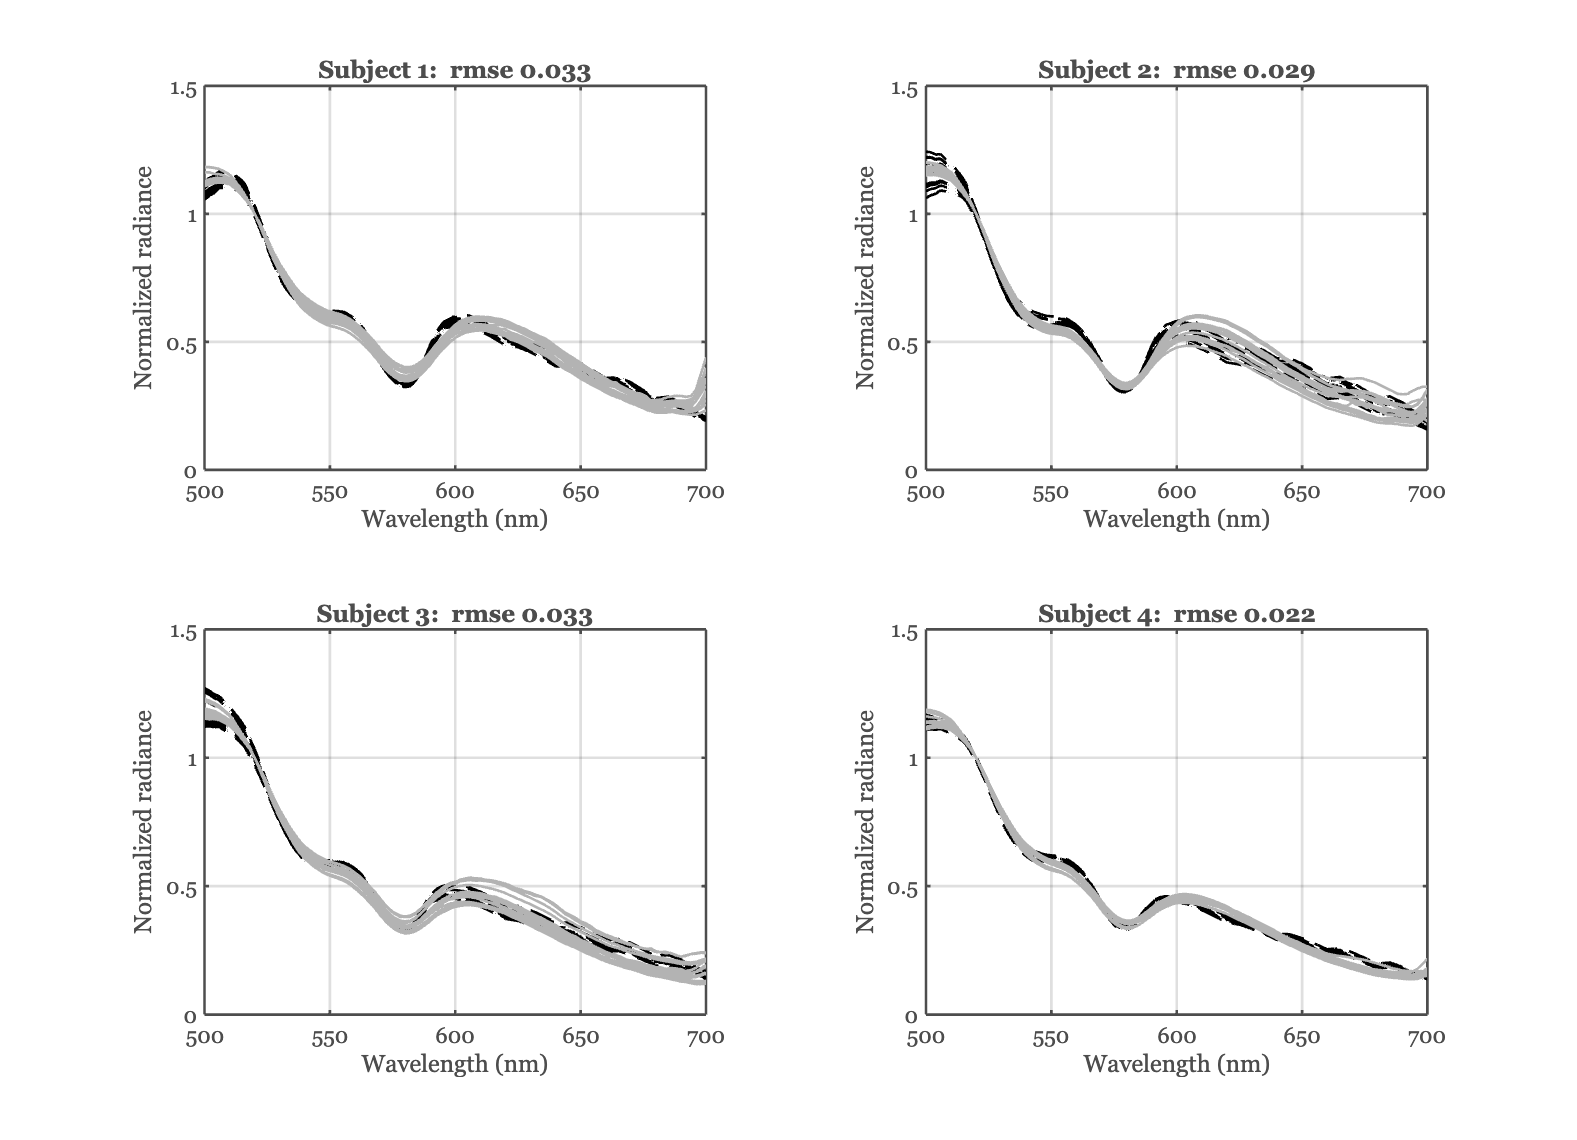

fluorophoreNamesLip = ["Collagen", "FAD"];

odLip = zeros(1,numel(subjects));
nLip = zeros(1,numel(subjects));
weights = cell(4,1);
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the lip data
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    lipData  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);
    nLip(ii) = size(lipData,2);

    % Find the blood optical density using only the first two columns of
    % saved fluorophores.
    [odLip(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,lipData,savedFluorophores(:,[1,2]));
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,lipData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance');
    set(gca,'ylim',[0 1.5]);
    title(sprintf('Subject %d:  rmse %.3f',ii,rmse(lipData(:),predicted(:))));
end
exportgraphics(gcf,'figure7.png','Resolution',150);

### Table of the lip weights and blood density

405 nm and 415 nm

oePrintModel(fluorophoreNamesLip,odLip,weights,nLip);

Subject 1 (N=14):
Blood log10(od) 1.06  Collagen: 17.34 ± 0.52 FAD: 0.63 ± 0.01 

Subject 2 (N=13):
Blood log10(od) 0.96  Collagen: 16.12 ± 1.41 FAD: 0.54 ± 0.03 

Subject 3 (N=14):
Blood log10(od) 0.80  Collagen: 13.12 ± 0.93 FAD: 0.49 ± 0.02 

Subject 4 (N=14):
Blood log10(od) 0.78  Collagen: 11.81 ± 0.38 FAD: 0.53 ± 0.02 



## Fit individually again, different excitation light (Figure 8)

Now with the 450 nm excitation

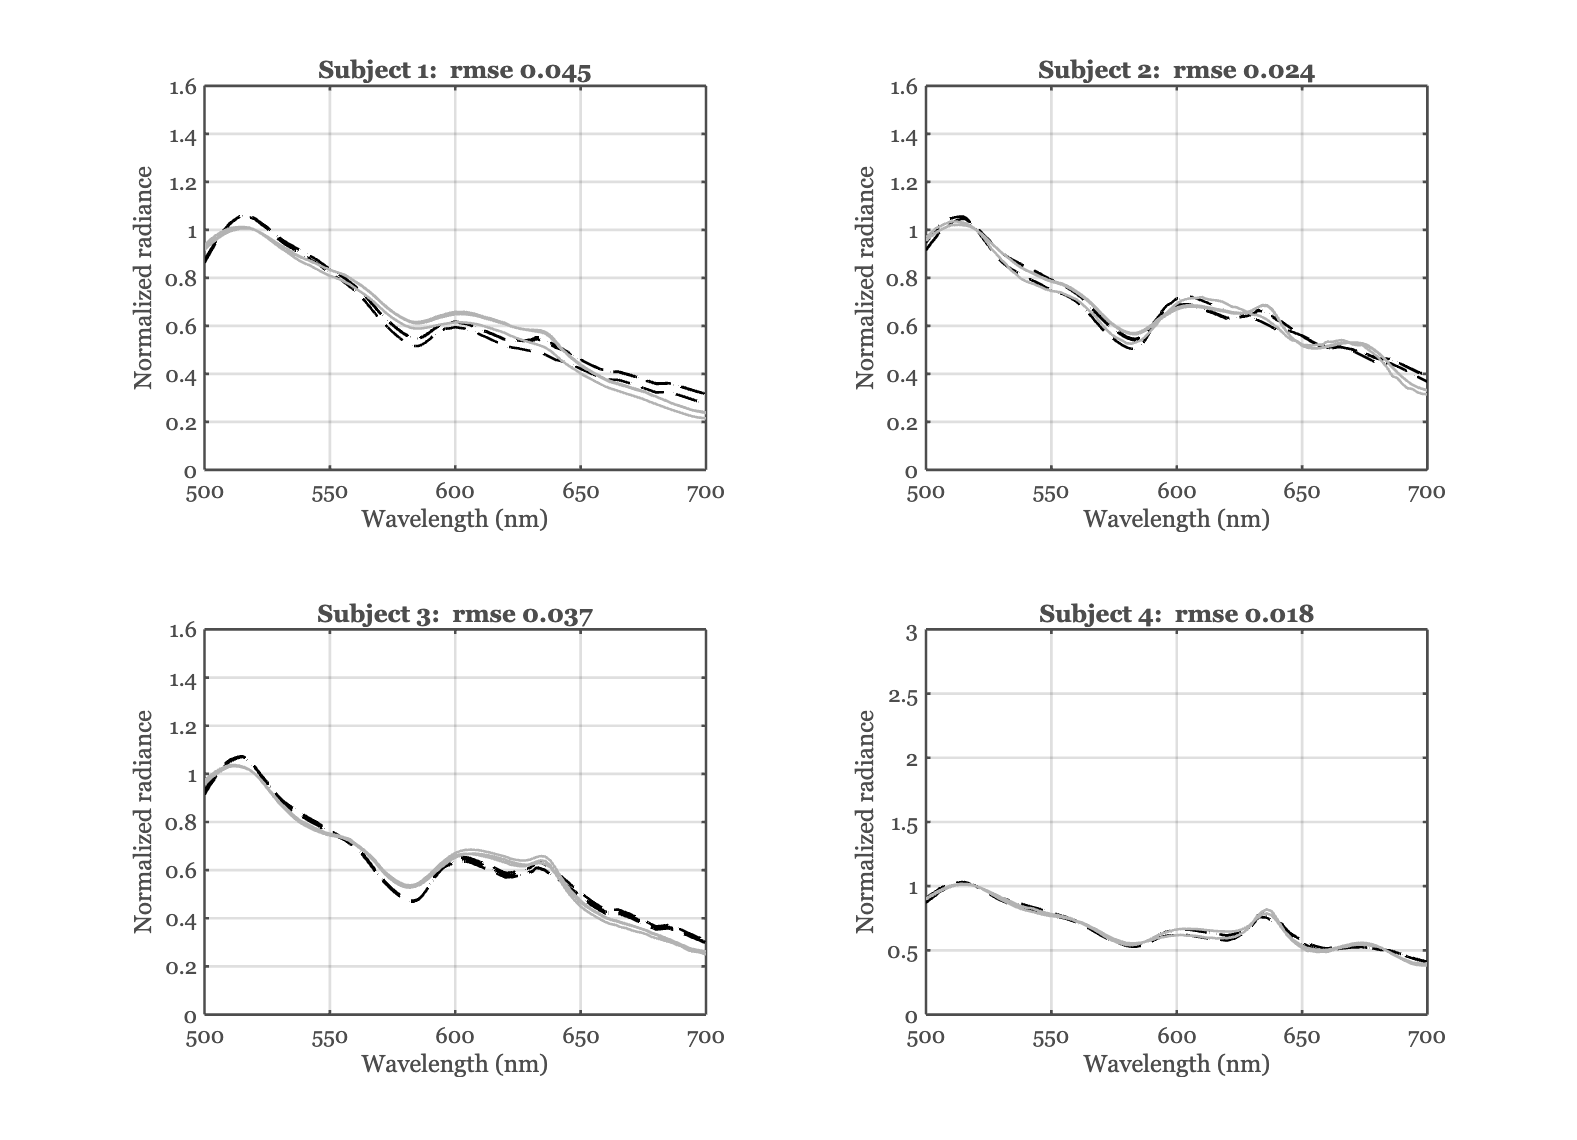

odTongue = zeros(1,numel(subjects));
nTongue450 = zeros(1,numel(subjects));
weights = cell(4,1);
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the tongue data
    tongueFiles450 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',450);
    tongueData  = oeReadFiles(tongueFiles450,'normalized wave',normWave,'wave',wave);
    nTongue450(ii) = size(tongueData,2);

    % Find the blood optical density
    [odTongue(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,tongueData,savedFluorophores);
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,tongueData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance');
    set(gca,'ylim',[0 1.6]);
    if ii==4, set(gca,'ylim',[0 3]); end
    title(sprintf('Subject %d:  rmse %.3f',ii,rmse(tongueData(:),predicted(:))));
end
exportgraphics(gcf,'figure8.png','Resolution',150);

### Here is the 450 nm table

oePrintModel(fluorophoreNames,odTongue,weights,nTongue450);

Subject 1 (N=3):
Blood log10(od) 1.24  Collagen: 8.90 ± 0.44 FAD: 0.72 ± 0.02 Porphyrin: 0.05 ± 0.02 Chlorophyll-a: 0.00 ± 0.00 Keratin: 0.30 ± 0.04 

Subject 2 (N=3):
Blood log10(od) 1.25  Collagen: 12.77 ± 1.87 FAD: 0.60 ± 0.00 Porphyrin: 0.06 ± 0.05 Chlorophyll-a: 0.02 ± 0.01 Keratin: 0.35 ± 0.03 

Subject 3 (N=3):
Blood log10(od) 1.23  Collagen: 13.83 ± 0.45 FAD: 0.71 ± 0.01 Porphyrin: 0.09 ± 0.01 Chlorophyll-a: 0.00 ± 0.00 Keratin: 0.20 ± 0.00 

Subject 4 (N=2):
Blood log10(od) 1.22  Collagen: 10.21 ± 1.38 FAD: 0.61 ± 0.03 Porphyrin: 0.24 ± 0.05 Chlorophyll-a: 0.09 ± 0.02 Keratin: 0.35 ± 0.01 



## Lip with the 450 nm excitation light (Figure 9)

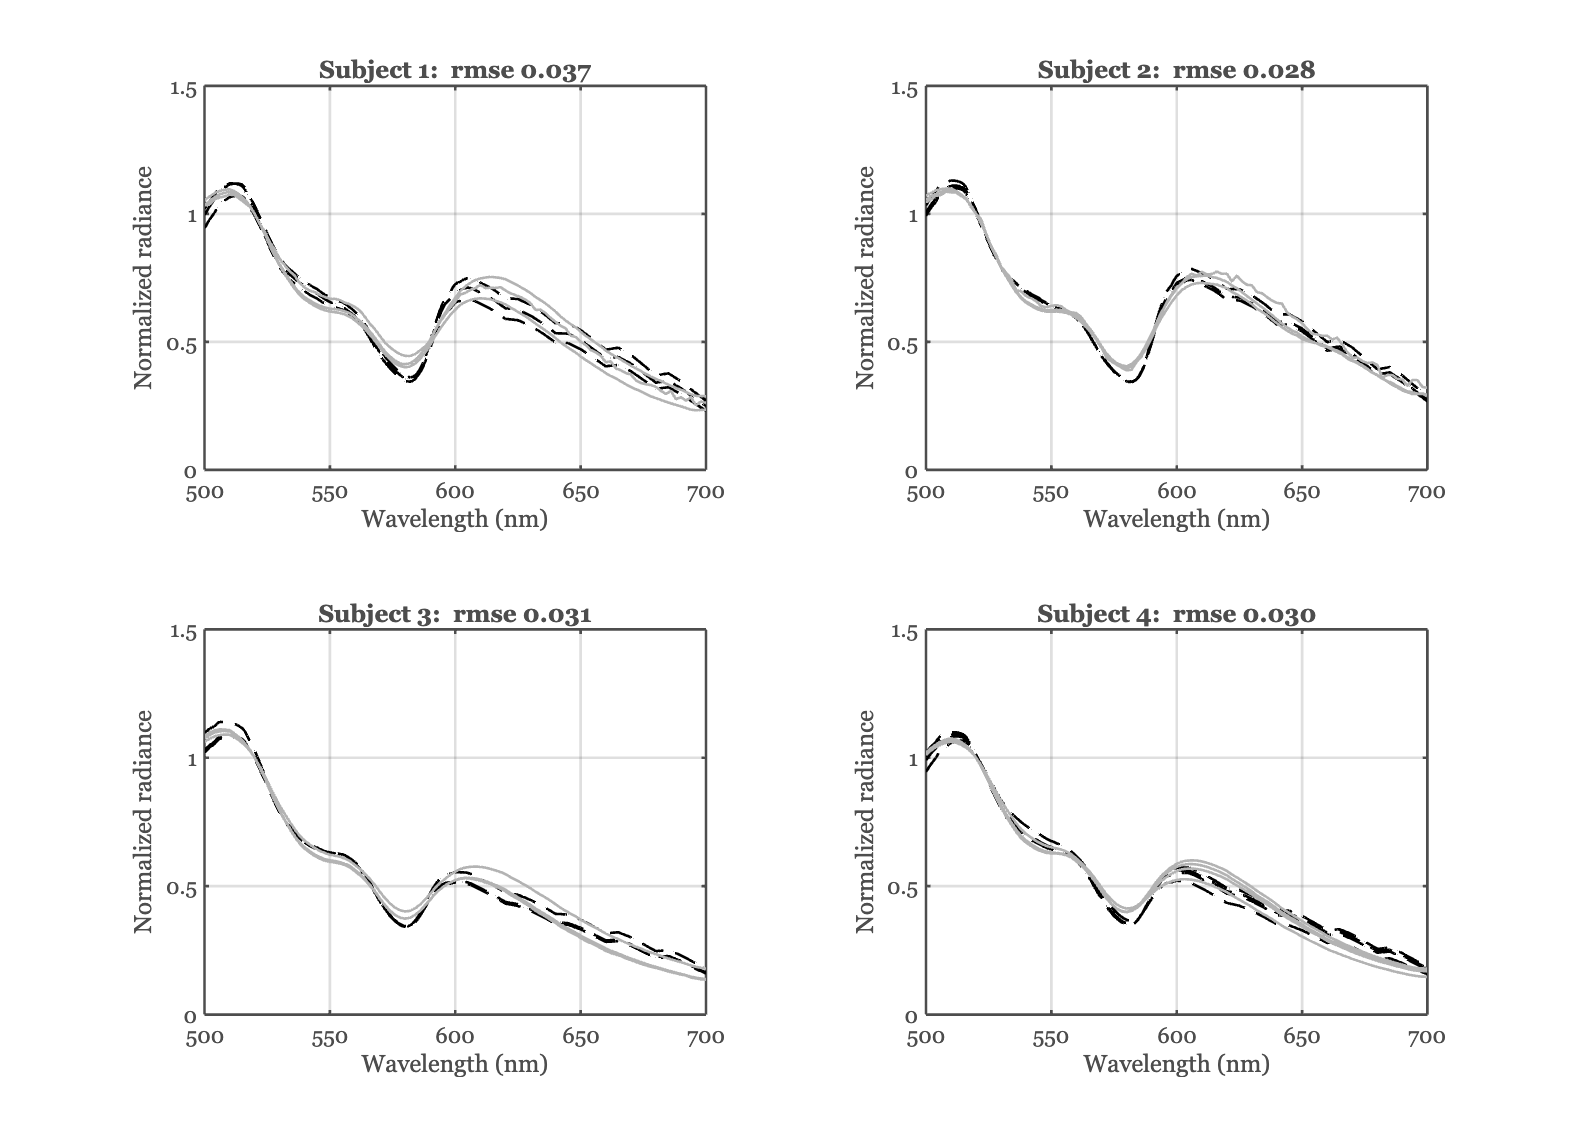

odLip = zeros(1,numel(subjects));
weights = cell(4,1);
nLip450 = zeros(1,numel(subjects));

ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the lip data
    lipFiles450 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',450);
    lipData  = oeReadFiles(lipFiles450,'normalized wave',normWave,'wave',wave);
    nLip450(ii) = size(lipData,2);

    % Find the blood optical density using only the first two columns of
    % saved fluorophores.
    [odLip(ii),weights{ii},finalFluorophores] = oeSolveBlood(wave,lipData,savedFluorophores(:,[1,2]));
    predicted = finalFluorophores*weights{ii};
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,lipData,'Color',[1 1 1]*0.7); grid on;
    xlabel('Wavelength (nm)'); ylabel('Normalized radiance');
    set(gca,'ylim',[0 1.5]);
    title(sprintf('Subject %d:  rmse %.3f',ii,rmse(lipData(:),predicted(:))));
end
exportgraphics(gcf,'figure9.png','Resolution',150);

### Table for 450 nm excitation.

fluorophoreNames = ["Collagen", "FAD"];
oePrintModel(fluorophoreNamesLip,odLip,weights,nLip450);

Subject 1 (N=3):
Blood log10(od) 1.24  Collagen: 22.18 ± 1.81 FAD: 0.75 ± 0.02 

Subject 2 (N=3):
Blood log10(od) 1.25  Collagen: 24.61 ± 0.97 FAD: 0.73 ± 0.00 

Subject 3 (N=3):
Blood log10(od) 1.02  Collagen: 14.58 ± 0.99 FAD: 0.66 ± 0.01 

Subject 4 (N=4):
Blood log10(od) 1.10  Collagen: 15.19 ± 1.21 FAD: 0.72 ± 0.02 

